% Let's set up a three segment sysetm:
syms v_x1 v_y1 omega_1;
syms v_x2 v_y2 omega_2;
syms v_x3 v_y3 omega_3;
syms Q_1 Q_2 Q_3;
assume([v_x1, v_y1, omega_1, v_x2 v_y2 omega_2, v_x3 v_y3 omega_3, Q_1 Q_2 Q_3], "Real");

twist_1 = [v_x1; v_y1; omega_1];
twist_2 = [v_x2; v_y2; omega_2];
twist_3 = [v_x3; v_y3; omega_3];

mat_twists = [twist_1, twist_2, twist_3];
Q = [Q_1; Q_2; Q_3];

syms x_0 y_0 theta_0
g_0 = Pose2.hat([x_0, y_0, theta_0]);
q = calc_external_wrench(mat_twists, Q, g_0);
q_vec = q(:);

v_twists = [twist_1; twist_2; twist_3];

J = simplify(jacobian(q_vec, v_twists));

J

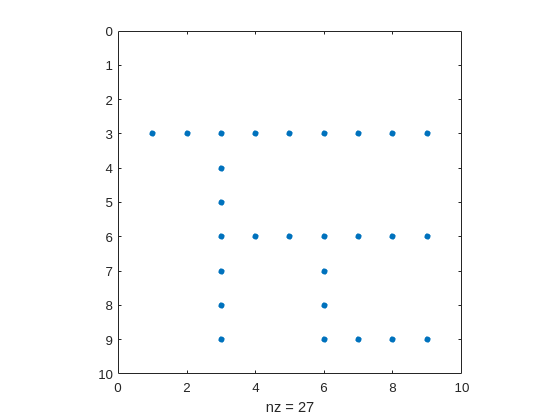

spy(J)

matlabFunction(J, "File", "J_external_3seg", "Vars", {theta_0, Q, twist_1, twist_2, twist_3});